# Logistic Growth Simulation 1.4

Gage Siebert 10/18/2018

## Assumptions

I assume that the phosphate is a resource for the organisms, but not the limiting factor. I neglect any other limiting factor and I also neglect the chance of any parasitic activity occuring.

## Simulation

Organisms/critters will have three traits and one variable: rate of energy/phosphate consumption, number of energy units/phosphates consumed before reproduction, number of energy units/phosphates consumed since last reproduction (variable), and drought resistance. The currency of this ecosystem will be a vaguely defined energy unit and it will begin with an arbitrary amount.

%rng('default') % For consistency
tic % Time the simulation
Gen=25; % Number of Desired Generations
MutationChance= 0; % Chance of Offspring Trait Mutating

% Initializing variables
InitialEnergy=100000;
InitialPhosphate=100000;
PhosphateData=zeros(1,Gen); 
PopulationData=zeros(1,Gen); 
AppetiteData=zeros(1,Gen);
FertilityData=zeros(1,Gen);
ResistanceData=zeros(1,Gen);
Availability=1; % ratio of origional food supply left (to be changed)

% Generating a seed population
%iPop=[rand(1,10);rand(1,10).*2+1.5;zeros(1,10);rand(1,10)./2+.5]; % appetite,fertility,stomach,resistance
iPop=[1; 1; 0; 0.9]; % Uniform population
Population=iPop;
% Generating Time Variance
Time=8.*ones(1,Gen);
for it=1:3:Gen
    Time(it)=Time(it)*1.5;
end

Now that the initial conditions are set, the simulation can begin.

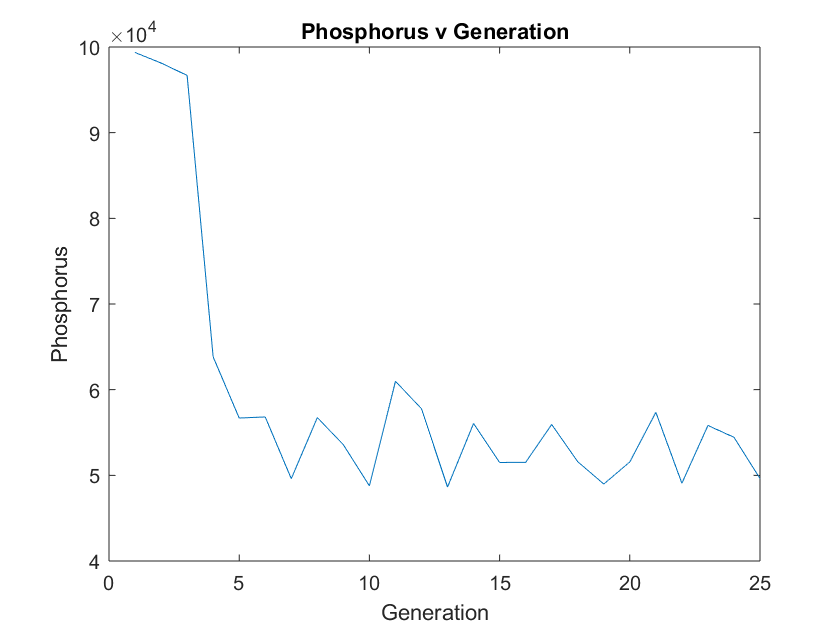

for Generation=1:1:Gen
    Phosphate=InitialPhosphate;
    Energy=InitialEnergy;
    
    for t=1:1:Time(Generation) % number of ticks per generation
        
        if Phosphate < 0 % to prevent weirdness from negative food supply
            Phosphate = 0;% but this should not happen anyway
            Availability = 0;
        end
        
        if Energy < 0 % to prevent weirdness from negative food supply
            Energy = 0;
            Availability = 0;
        end
        
        for n=1:1:length(Population(1,:))
            Phosphate=Phosphate-sum(Population(1,n)*Availability^2);  % eating part 1 of 3
            Energy=Energy-sum(Population(1,n)*Availability^2); % eating part 2 of 3
            Population(3,n)=Population(3,n)+Population(1,n)*Availability^2;  % eating part 3 of 3
        end
        s=0;
        Baby=zeros(4,length(Population(1,:)));
        for i=1:1:length(Population(1,:))
            
            if Population(2,i) < Population(3,i) % test to see if critter is ready to reproduce
                Population(3,i)=Population(3,i)-Population(2,i);
                s=s+1;
                if rand(1) < MutationChance % chance appetite is changed
                    if rand(1) < 1/10 % chance it goes up
                        Baby(1,s)=Population(1,i)+.01*Population(1,i); % goes up 1 percent
                    else
                        Baby(1,s)=Population(1,i)-.01*Population(1,i); % goes down 1 percent
                    end
                else
                    Baby(1,s)=Population(1,i);
                end
             
                if rand(1) < MutationChance % chance fertility is changed
                    if rand(1) < 1/10 % chance it goes up
                        Baby(2,s)=Population(2,i)+.01*Population(2,i); % goes up 1 percent
                    else
                        Baby(2,s)=Population(2,i)-.01*Population(2,i); % goes down 1 percent
                    end
                else
                    Baby(2,s)=Population(2,i);
                end
                
                if rand(1) < MutationChance % chance resistance is changed
                    if rand(1) < 1/10 % chance it goes up
                        Baby(4,s)=Population(4,i)+.01*Population(4,i); % goes up 1 percent
                    else
                        Baby(4,s)=Population(4,i)-.01*Population(4,i); % goes down 1 percent
                    end
                else
                    Baby(4,s)=Population(4,i);
                end
            end
        end
        Baby=Baby(:,1:s);
        Population=[Population Baby];
        
        Availability=Energy/InitialEnergy; % update
        HitList=zeros(1,length(Population(1,:))); % initialize variable
        j=0; % initialize variable (enables preallocation)
        for k=1:1:length(Population(1,:)) % check every member
            if Population(4,k) < randn(1)*.25+.5 % test if it will survive (can be dampened to increase survival rate)
                j=j+1;
                HitList(j)=k; % Mark it for death
                Phosphate=Phosphate+Population(3,k)+Population(2,k); % release sequestered Phosphate
            end
        end
        HitList=HitList(1:j);
        Population(:,HitList)=[]; % Darwin Award Ceremony  
        Population=[Population iPop]; % De Novo Spawns
    end
    
    % Data Collection Section
    PhosphateData(Generation)=Phosphate; 
    PopulationData(Generation)=length(Population(1,:));
    AppetiteData(Generation)=sum(Population(1,:))/length(Population(1,:));
    FertilityData(Generation)=sum(Population(2,:))/length(Population(1,:));
    ResistanceData(Generation)=sum(Population(4,:))/length(Population(1,:));
    %End of Data Collection Section
    
    % Kill about 90 percent of population before next gen starts
    luck=rand(1,length(Population(1,:))); 
    HitList2=zeros(1,length(Population(1,:)));
    h=0;
    n=normrnd(.9,.03);
    for m=1:1:length(Population(1,:))
        if luck(m) < n % select n percent of population
            h=h+1;
            HitList2(h)=m;
        end
    end
    HitList2=HitList2(1:h);
    Population(:,HitList2)=[];
end

plot(1:1:Gen,PhosphateData) 
title('Phosphorus v Generation')
xlabel('Generation')
ylabel('Phosphorus')

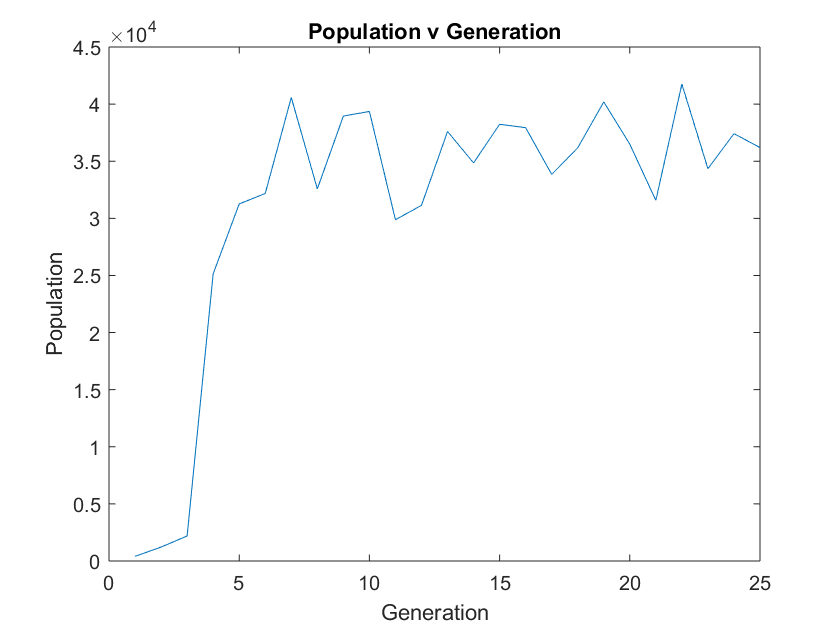

plot(1:1:Gen,PopulationData) 
title('Population v Generation')
xlabel('Generation')
ylabel('Population')


if 0 < MutationChance
    plot(1:1:Gen,AppetiteData) 
    title('Appetite v Generation')
    xlabel('Generation')
    ylabel('Appetite')
    plot(1:1:Gen,FertilityData) 
    title('Fertility v Generation')
    xlabel('Generation')
    ylabel('Fertility')
    plot(1:1:Gen,ResistanceData) 
    title('Resistance v Generation')
    xlabel('Generation')
    ylabel('Resistance')
end

toc

Elapsed time is 55.603892 seconds.
